t = 0:0.01:500; 
K_critical = -0.47;

G_closed = feedback(G_s * K_critical, 1);

[y, t_out] = impulse(G_closed, t);

[pks, locs] = findpeaks(y, t_out);

if length(locs) > 1
    T_u = mean(diff(locs));
    fprintf('Znaleziono oscylacje!\n');
    fprintf('Wzmocnienie krytyczne Ku = %.4f\n', K_critical);
    fprintf('Okres krytyczny       Tu = %.4f s\n', T_u);
    
    Kp = 0.6 * K_critical;
    Ti = 0.5 * T_u;
    Td = 0.125 * T_u;
    
    Ki = Kp / Ti;
    Kd = Kp * Td;
        
    fprintf('\n=== ZALECANE NASTAWY PID ===\n');
    fprintf('Kp = %.4f\n', Kp);
    fprintf('Ki = %.4f\n', Ki);
    fprintf('Kd = %.4f\n', Kd);
    fprintf('============================\n');
else
    fprintf('Brak wystarczającej liczby oscylacji. Zmień K_critical.\n');
end

Brak wystarczającej liczby oscylacji. Zmień K_critical.


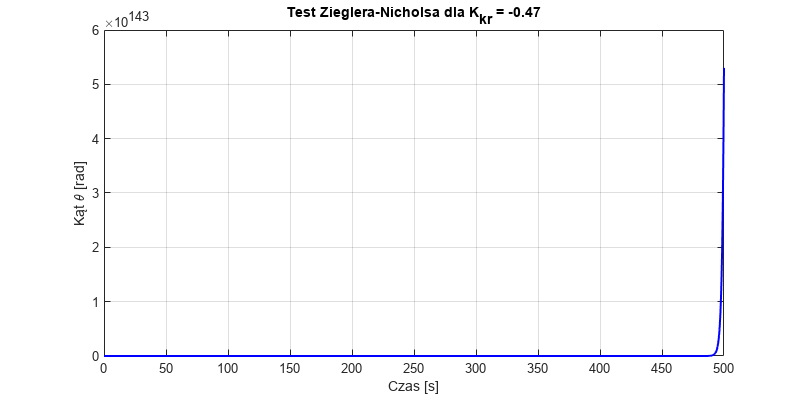


figure('Position', [100, 100, 800, 400]);
plot(t_out, y, 'b', 'LineWidth', 1.5);
title(['Test Zieglera-Nicholsa dla K_{kr} = ' num2str(K_critical)]);
xlabel('Czas [s]');
ylabel('Kąt \theta [rad]');
grid on;

print('odp_skok_zigler.png', '-dpng', '-r400');